# **02. Graphics**

**Práctica:** 02

**Nombre: **Mateo Simbaña

**Fecha: **6 de enero del 2024

## 1. Basic Plotting Functions 

### 1.1 Creating a Plot

La función `plot` tiene diferentes formas, según los argumentos de entrada.

• Si `y` es un vector, `plot(y) `produce una gráfica lineal por partes de los elementos de `y vs `el índice de los elementos de `y`.

• Si especifica dos vectores como argumentos, `plot(x,y) `produce una gráfica de `y` vs `x`.

x = 0:pi/100:2*pi;
y = sin(x);
plot(x,y)

Agregue etiquetas de eje y un título. Los caracteres \pi en la función `xlabel `crean el símbolo `π`. La propiedad `FontSize` en la función `title` aumenta el tamaño del texto utilizado para el título.

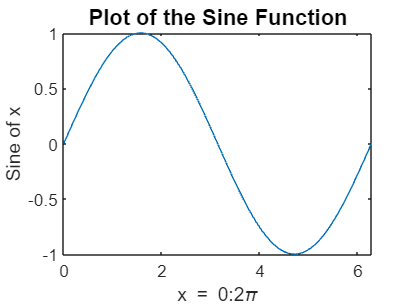

xlabel('x = 0:2\pi')
ylabel('Sine of x')
title('Plot of the Sine Function','FontSize',12)

### 1.2 Plotting Multiple Data Sets in One Graph

Múltiples argumentos de pares `x-y `crean múltiples gráficos con una sola llamada a `plot`. MATLAB utiliza un color diferente para cada línea.

x = 0:pi/100:2*pi;
y = sin(x);
y2 = sin(x-.25);
y3 = sin(x-.5);
plot(x,y,x,y2,x,y3)

La función `legend` proporciona una manera sencilla de identificar las líneas individuales:

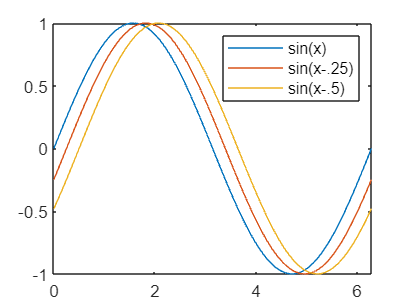

legend('sin(x)','sin(x-.25)','sin(x-.5)')

### 1.3 Specifying Line Styles and Colors

Es posible especificar color, estilos de línea y marcadores (como signos más o círculos) cuando traza sus datos usando el comando `plot`:

`plot(x,y,'color_style_marker') `

`color_style_marker `contiene de uno a cuatro caracteres (entre comillas simples) construidos a partir de un color, un estilo de línea y un tipo de marcador. Por ejemplo:

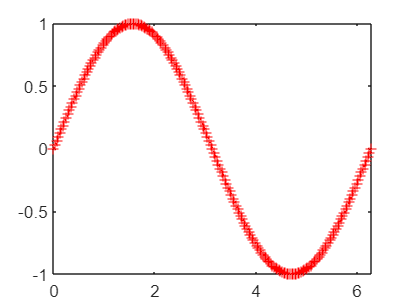

plot(x,y,'r:+')

Donde, se traza los datos usando una línea de puntos rojos y se coloca un marcador + en cada punto de datos.

### 1.4 Plotting Lines and Markers

Si especifica un tipo de marcador, pero no un estilo de línea, MATLAB crea el gráfico utilizando sólo marcadores, pero ninguna línea. Por ejemplo:

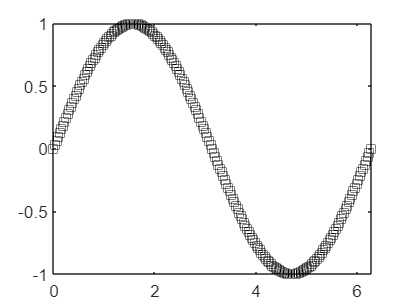

plot(x,y,'ks')

La siguiente declaración traza una línea de puntos rojos y coloca marcadores de signo más en cada punto de datos:

plot(x,y,'r:+')

#### 1.4.1 Placing Markers at Every Tenth Data Point 

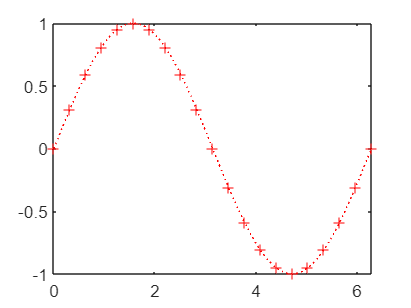

x1 = 0:pi/100:2*pi;
x2 = 0:pi/10:2*pi;
plot(x1,sin(x1),'r:',x2,sin(x2),'r+')

### 1.5 Graphing Imaginary and Complex Data 

Cuando pasa valores complejos como argumentos para trazar, MATLAB ignora la parte imaginaria, excepto cuando pasa un único argumento complejo. Para este caso especial, el comando es un atajo para una gráfica de la parte imaginaria versus la parte real. Por lo tanto,

`plot(Z) `

donde `Z `es un vector o matriz complejo, equivale a

`plot(real(Z),imag(Z)) `

Las siguientes declaraciones dibujan un polígono de 20 lados con pequeños círculos en los vértices.

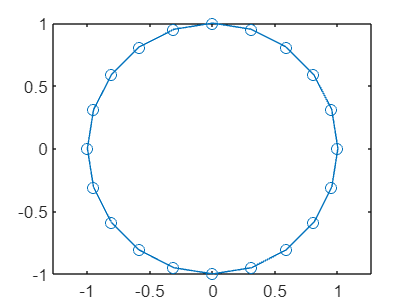

t = 0:pi/10:2*pi;
plot(exp(1i*t),'-o')
axis equal

### 1.6 Adding Plots to an Existing Graph 

El comando `hold` permite agregar gráficos a un gráfico existente. Cuando escribes:

`hold on`

MATLAB no reemplaza el gráfico existente cuando se emite otro comando de trazado. En cambio, MATLAB combina el nuevo gráfico con el gráfico actual.

Por ejemplo, estas declaraciones primero crean un gráfico de superficie de la función de picos y luego superponen un gráfico de contorno de la misma función:

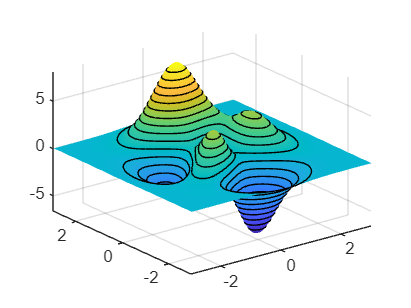

[x,y,z] = peaks;
% Create surface plot
surf(x,y,z)
% Remove edge lines a smooth colors
shading interp
% Hold the current graph
hold on
% Add the contour graph to the pcolor graph
contour3(x,y,z,20,'k')
% Return to default
hold off

### 1.7 Figure Windows

Las funciones de trazado abren automáticamente una nueva ventana de figura si aún no hay ventanas de figura creadas. Si hay varias ventanas de figuras abiertas, MATLAB usa la designada como "figura actual" (generalmente, la última figura utilizada).

Para convertir una ventana de figura existente en la figura actual, puede hacer clic con el mouse mientras el puntero está en esa ventana o puede escribir:

`figure(n)`

donde` n` es el número en la barra de título de la figura.

Para abrir una nueva ventana de figura y convertirla en la figura actual, escribir:

`figure`

#### 1.7.1 Clearing the Figure for a New Plot

Cuando ya existe una figura, la mayoría de los comandos de trazado borran los ejes y utilizan esta figura para crear el nuevo trazado. Sin embargo, estos comandos no restablecen las propiedades de la figura, como el color de fondo o el mapa de colores. Si ha configurado alguna propiedad de figura en el gráfico anterior, puede usar el comando `clf `con la opción `reset `antes de crear su nuevo gráfico para restaurar las propiedades de la figura a sus valores predeterminados: 

`clf reset`

### 1.8 Displaying Multiple Plots in One Figure

El comando `subplot` permite mostrar varios trazados en la misma ventana o imprimirlos en la misma hoja de papel. Se lo utiliza de la siguiente manera:

`subplot(m,n,p)`

Por ejemplo, estas declaraciones trazan datos en tres subregiones de la ventana de la figura:

% x = 0:pi/20:2*pi;
% subplot(3,1,1); plot(sin(x))
% subplot(3,1,2); plot(cos(x))
% subplot(3,1,3); plot(sin(x).*cos(x))

### 1.9 Controlling the Axes

El comando `axes` proporciona una serie de opciones para configurar la escala, la orientación y la relación de aspecto de los gráficos.

#### 1.9.1 Automatic Axis Limits and Tick Marks

De forma predeterminada, MATLAB encuentra los máximos y mínimos de los datos y elige los límites de los ejes para abarcar este rango. MATLAB selecciona los límites y los valores de las marcas de eje para producir un gráfico que muestra claramente los datos. Sin embargo, puede establecer sus propios límites utilizando las funciones `axis` o `xlim`,` ylim `y `zlim`.

#### 1.9.2 Setting Axis Limits

El comando `axis` permite especificar sus propios límites:

`axis([xmin xmax ymin ymax])`

o para gráficos tridimensionales:

`axis([xmin xmax ymin ymax zmin zmax])`

Con el siguiente comando se habilita la selección automática de límites nuevamente:

`axis auto`

#### 1.9.3 Setting the Axis Aspect Ratio

El comando de eje también permite especificar una serie de modos predefinidos. Por ejemplo:

`axis square`

hace que el eje `x` y el eje `y` tengan la misma longitud.

`axis equal`

hace que los incrementos de las marcas individuales en los ejes `x` e `y` tengan la misma longitud. Esto significa:

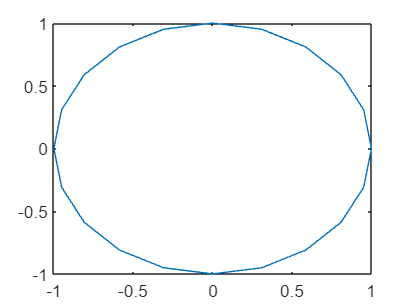

plot(exp(1i*(0:pi/10:2*pi)))

seguido de `axis square` o `axis equal `convierte el óvalo en un círculo propio:

`axis auto normal`

devuelve la escala del eje a su modo automático predeterminado.

#### 1.9.4 Setting Axis Visibility

Puede utilizar el comando `axis` para hacer que el eje sea visible o invisible.

`axis on`

hace visibles los ejes. Este es el valor predeterminado.

`axis off`

hace que los ejes sean invisibles.

#### 1.9.5 Setting Grid Lines 

El comando `grid` activa y desactiva las líneas de la cuadrícula. La declaración:

`grid on`

activa las líneas de la cuadrícula y

`grid off`

las vuelve a desactivar.

### 1.10 Adding Axis Labels and Titles 

Este ejemplo muestra cómo crear un gráfico y mejorar su presentación:

    • Definir los límites de los ejes `x `e `y `(`axis`)

    • Etiquetar los ejes `x `e` y `(`xlabel`, `ylabel`)

    • Agregar un título (`title`)

    • Agregar una nota de texto en el gráfico (`text`)

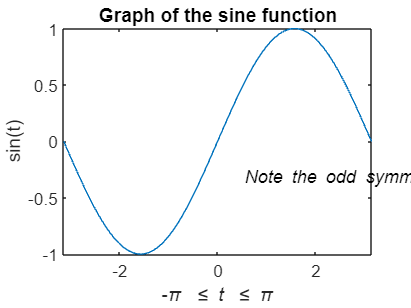

t = -pi:pi/100:pi;
y = sin(t);
plot(t,y)
axis([-pi pi -1 1])
xlabel('-\pi \leq {\itt} \leq \pi')
ylabel('sin(t)')
title('Graph of the sine function')
text(0.5,-1/3,'{\itNote the odd symmetry.}')

### 1.11 Saving Figures

Guarde una figura seleccionando **Save** en el menú **File**. Esto escribe la figura en un archivo, incluidos los datos de propiedad, sus menús, controles de interfaz de usuario y todas las anotaciones (es decir, la ventana completa). Si no has guardado el figura anterior, se muestra el cuadro de diálogo **Save as**. Este cuadro de diálogo proporciona opciones para guardar la figura como un archivo `.fig `o exportarla a un formato gráfico.

Si ya guardó la figura anteriormente, al usar **Save** nuevamente se guarda la figura “silenciosamente”, sin mostrar el cuadro de diálogo **Save as**.

Para guardar una figura usando un formato de gráficos estándar para usar con otras aplicaciones, como TIFF o JPG, seleccione **Save as** (o **Export Setup**, si desea control adicional) en el menú **File**.

También puedes guardar desde la línea de comando:

• Utilice la función `savefig `para guardar una figura y los objetos gráficos que contiene como un archivo` .fig`.

• Utilice el comando `saveas`, incluidas las opciones para guardar la figura en una variedad de formatos.

#### 1.11.1 Loading a Figure 

Puede cargar figuras en MATLAB utilizando estas funciones:

    • Utilice la función `openfig `para cargar figuras guardadas como archivos `.fig`.

    • Utilice la función `imread `para leer archivos de gráficos estándar (incluidas las figuras         guardadas) en MATLAB.

#### 1.11.2 Generating MATLAB Code to Recreate a Figure

Puede generar código MATLAB que recrea una figura y el gráfico que contiene seleccionando **Generate code **en el menú **File** de la figura. Esta opción es particularmente útil si ha desarrollado un gráfico usando herramientas de trazado y desea crear un gráfico similar usando los mismos datos o diferentes.

### 1.12 Saving Workspace Data 

Puede guardar las variables en su espacio de trabajo seleccionando **Save Workspace As** en el menú **File** de la figura. Puede recargar los datos guardados utilizando el elemento **Import Data **en el menú **File** de la figura. MATLAB admite una variedad de formatos de archivos de datos, incluidos archivos de datos MATLAB, que tienen una extensión `.mat.`

## 2. Creating Mesh and Surface Plots

### 2.1 About Mesh and Surface Plots

MATLAB define una superficie mediante las coordenadas `z `de puntos sobre una cuadrícula en el plano `x-y`, utilizando líneas rectas para conectar puntos adyacentes. Las funciones `mesh` y `surf `muestran superficies en tres dimensiones.

    • `mesh` produce superficies de estructura alámbrica que colorean sólo las líneas que conectan los puntos de definición.

    • `surf` muestra en color tanto las líneas de conexión como las caras de la superficie.

MATLAB colorea superficies asignando valores de datos `z `a índices en el mapa de colores de la figura.

### 2.2 Visualizing Functions of Two Variables

Para mostrar una función de dos variables, `z = f (x,y)`,

- Genere matrices `X` e `Y `que constan de filas y columnas repetidas, respectivamente, a lo largo del dominio de la función.

- Usa `X` e `Y `para evaluar y representar gráficamente la función.

La función `meshgrid` transforma el dominio especificado por un solo vector o dos vectores `x `e `y `en matrices `X `e `Y `para usar en la evaluación de funciones de dos variables. Las filas de `X `son copias del vector `x `y las columnas de `Y `son copias del vector `y`.

#### 2.2.1 Graphing the sinc Function

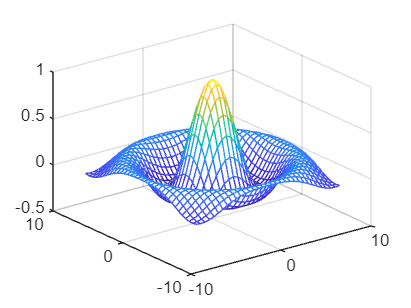

[X,Y] = meshgrid(-8:.5:8);
R = sqrt(X.^2 + Y.^2) + eps;
Z = sin(R)./R;
mesh(X,Y,Z)

De forma predeterminada, MATLAB utiliza el mapa de colores actual para colorear la malla.

#### 2.2.2 Colored Surface Plots 

Este ejemplo muestra cómo graficar la función `sinc` como un gráfico de superficie, especificar un mapa de colores y agregar una barra de colores para mostrar la asignación de datos al color.

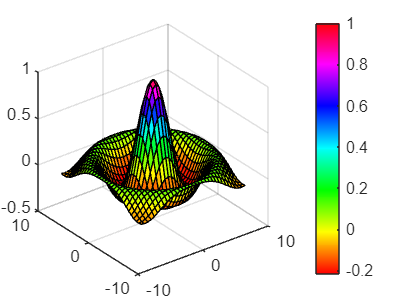

[X,Y] = meshgrid(-8:.5:8);
R = sqrt(X.^2 + Y.^2) + eps;
Z = sin(R)./R;
surf(X,Y,Z)
colormap hsv
colorbar

#### 2.2.3 Making Surfaces Transparent

Este ejemplo muestra cómo hacer que las caras de una superficie sean transparentes en distintos grados. La transparencia (denominada valor alfa) se puede especificar para todo el objeto o puede basarse en un mapa alfa, que se comporta de manera similar a los mapas de colores.

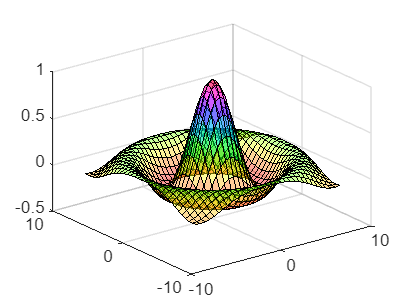

[X,Y] = meshgrid(-8:.5:8);
R = sqrt(X.^2 + Y.^2) + eps;
Z = sin(R)./R;
surf(X,Y,Z)
colormap hsv
alpha(.4)

#### 2.2.4 Illuminating Surface Plots with Lights

Este ejemplo muestra la misma superficie que los ejemplos anteriores, pero la colorea de rojo y elimina las líneas de malla. Luego se agrega un objeto ligero a la izquierda de la "cámara" (la cámara es el lugar en el espacio desde donde se ve la superficie).

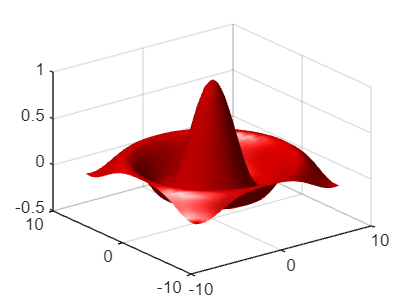

[X,Y] = meshgrid(-8:.5:8);
R = sqrt(X.^2 + Y.^2) + eps;
Z = sin(R)./R;
surf(X,Y,Z,'FaceColor','red','EdgeColor','none')
camlight left;
lighting phong

#### 2.2.5 Manipulating the Surface

La barra de herramientas de figuras y la barra de herramientas de cámara brindan formas de explorar gráficos tridimensionales de forma interactiva. Muestre la barra de herramientas de la cámara seleccionando **Camera Toolbar** de la cámara en el menú **View** de la figura.

Estas herramientas permiten mover la cámara alrededor del objeto de la superficie, hacer zoom, agregar iluminación y realizar otras operaciones de visualización sin emitir comandos.

## 3. Display Images

### 3.1 Image Data

Puede mostrar una matriz numérica 2D como una imagen. En las imágenes, los elementos de la matriz determinan el brillo o el color de las imágenes. Por ejemplo, a continuación cargamos una matriz de imágenes y su mapa de colores:

load durer
whos

  Name           Size               Bytes  Class     Attributes

  A              1x5                   40  double              
  B              1x5                   40  double              
  R             33x33                8712  double              
  X            648x509            2638656  double              
  Y             33x33                8712  double              
  Z             33x33                8712  double              
  a              1x1                    8  double              
  ans            1x1                    8  double              
  caption        2x28                 112  char                
  fact           1x1                    8  double              
  i              1x1                    8  double              
  k              1x1                    8  double              
  map          128x3                 3072  double              
  n              1x1                    8  double              
  r              1x1                   

Para mostrar la imagen, usamos la función `imshow`:

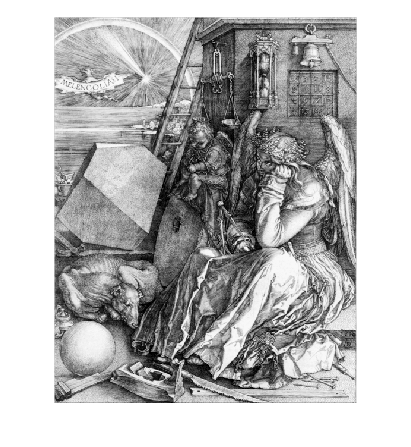

imshow(X,map)

Se reproduce el grabado de  Albrecht Dürer's.

### 3.2 Reading and Writing Images 

Se pueden leer archivos de imagen estándar (TIFF, JPEG, PNG, etc.) utilizando la función `imread`. El tipo de datos devueltos por `imread` depende del tipo de imagen que se esté leyendo.

También se pueden escribir datos de MATLAB en una variedad de formatos de imagen estándar utilizando la función `imwrite`.

## 4. Printing Graphics

### 4.1 Overview of Printing 

Puede imprimir una figura de MATLAB directamente en una impresora conectada a su computadora o puede exportar la figura a uno de los formatos de archivos de gráficos estándar que admite MATLAB. Hay dos maneras de imprimir y exportar figuras:

    • Utilizando las opciones GUI **Print**, **Print Preview** o **Export Setup** en el menú **File**.

    • Utilizando el comando **print **para imprimir o exportar la figura desde la línea de comando.

El comando `print` proporciona un mayor control sobre los controladores y los formatos de archivo. El cuadro de diálogo Vista previa de impresión brinda mayor control sobre el tamaño de las figuras, las proporciones, la ubicación y los encabezados de página.

### 4.2 Printing from the File Menu

Hay dos opciones de menú en el menú **File** que pertenecen a la impresión:

• La opción **Print Preview** muestra un cuadro de diálogo que le permite diseñar y diseñar figuras para imprimir mientras obtiene una vista previa de la página de salida, y desde donde puede imprimir la figura. Incluye opciones

que anteriormente formaban parte del cuadro de diálogo Configurar página.

• La opción **Print** muestra un cuadro de diálogo que le permite elegir una impresora, seleccionar opciones de impresión estándar e imprimir la figura.

Se utiliza  **Print Preview** para determinar si el resultado impreso es el que se desea. 

### 4.3 Exporting the Figure to a Graphics File

La opción **Export Setup** en el menú **File** abre una GUI que permite configurar características gráficas, como el tamaño del texto, la fuente y el estilo, para las figuras que guarda como archivos gráficos. El cuadro de diálogo Configuración de exportación permite definir y aplicar plantillas para personalizar y estandarizar la salida. Después de la configuración, se puede exportar la figura a varios formatos de archivos de gráficos estándar, como EPS, PNG y TIFF.

### 4.4 Using the Print Command 

El comando de impresión proporciona más flexibilidad en el tipo de salida enviada a la impresora y permite controlar la impresión desde archivos de funciones y scripts. El resultado puede enviarse directamente a la impresora predeterminada o almacenarse en un archivo de salida específico. Está disponible una amplia variedad de formatos de salida, incluidos TIFF, JPEG y PNG.

Por ejemplo, esta declaración guarda el contenido de la ventana de la figura actual como un gráfico PNG en el archivo llamado `magicsquare.png`.

`print -dpng magicsquare.png`

Para guardar la figura con el mismo tamaño que la figura en la pantalla, utilizamos estas instrucciones:

`set(gcf,'PaperPositionMode','auto') `

`print -dpng -r0 magicsquare.png`

Para guardar la misma figura como un archivo TIFF con una resolución de 200 ppp, usamos el siguiente comando:

`print -dtiff -r200 magicsquare.tiff`

Si escribimos `print` en la línea de comando la figura actual se imprime en la impresora predeterminada.

## 5. Working with Graphics Objects

### 5.1 Graphics Objects

Los objetos gráficos son elementos básicos utilizados para mostrar gráficos. Estos objetos están organizados en una jerarquía.

Cuando llama a una función de trazado, MATLAB crea el gráfico utilizando varios objetos gráficos, como una ventana de figura, ejes, líneas, texto, etc. Cada objeto tiene un conjunto fijo de propiedades, que puede utilizar para controlar el comportamiento y la apariencia del gráfico.

Por ejemplo, la siguiente declaración crea un gráfico de barras a partir de los datos de la variable `y` y establece propiedades que reflejan el aspecto de las barras:

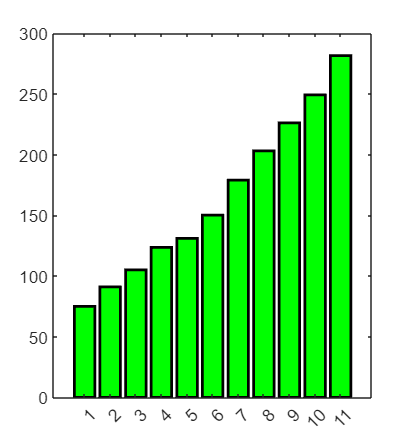

y = [75 91 105 123.5 131 150 179 203 226 249 281.5];
bar(y,'FaceColor','green','EdgeColor','black','LineWidth',1.5)

#### 5.1.1 Common Graphics Objects 

Cuando llama a una función para crear un gráfico, MATLAB crea una jerarquía de objetos gráficos. Por ejemplo, llamar a la función `plot` crea los siguientes objetos gráficos:

    • **Figure: **ventana que contiene ejes, barras de herramientas, menús, etc.

    • **Axes: **sistema de coordenadas que contiene el objeto que representa los datos.

    • **Line:** líneas que representan el valor de los datos pasados a la función de trazado.

    •** Text: **etiquetas para marcas de ejes y títulos y anotaciones opcionales.

#### 5.1.2 Access Object Properties

Las funciones de trazado pueden devolver los objetos utilizados para crear el gráfico. Por ejemplo, las siguientes declaraciones crean un gráfico y devuelven el objeto de línea creado por la función de trazado:

x = 1:10;
y = x.^3;
h = plot(x,y);

Utilizamos `h` para establecer las propiedades del objeto de línea. Por ejemplo, establecemos su propiedad `Color`.

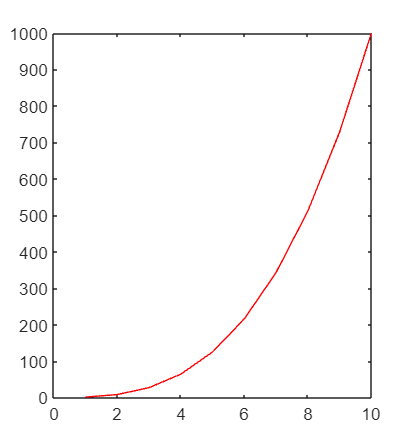

h.Color = 'red';

También se pueden especificar las propiedades de la línea cuando llamamos a la función de trazado.

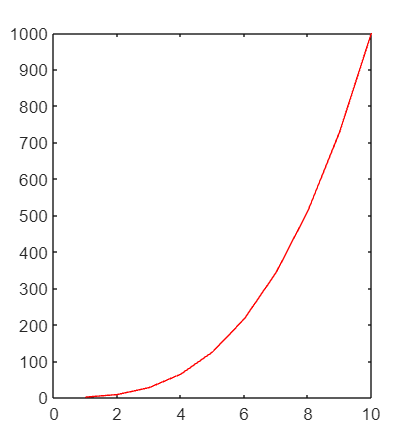

h = plot(x,y,'Color','red');

Por último, se pueden consultar las propiedades de la línea para ver el valor actual:

h.LineWidth

ans =           0.50


#### 5.1.3 Finding the Properties of an Object

Para ver las propiedades de un objeto, escribir:

`get(h)`

MATLAB devuelve una lista de las propiedades del objeto con los valores actuales.

Para ver las propiedades de un objeto con información sobre posibles valores, escribir:

`set(h)`

### 5.2 Setting Object Properties 

Se pueden configurar varias propiedades a la vez utilizando la función `set`.

#### 5.2.1 Setting Properties of Existing Objects

Para establecer la misma propiedad con el mismo valor en varios objetos, utilizamos la función `set`.

Por ejemplo, las siguientes declaraciones trazan una matriz de 5 por 5 y luego establecen la propiedad `Marker `en cuadrado y la propiedad `MarkerFaceColor `en verde.

y = magic(5);
h = plot(y);
set(h,'Marker','s','MarkerFaceColor','g')

En este caso, `h` es un vector que contiene cinco identificadores, uno para cada una de las cinco líneas del gráfico. La declaración `set `establece las propiedades `Marker `y `MarkerFaceColor `de todas las líneas en el mismo valor.

Para establecer un valor de propiedad en un objeto, indexamos en la matriz de identificadores:

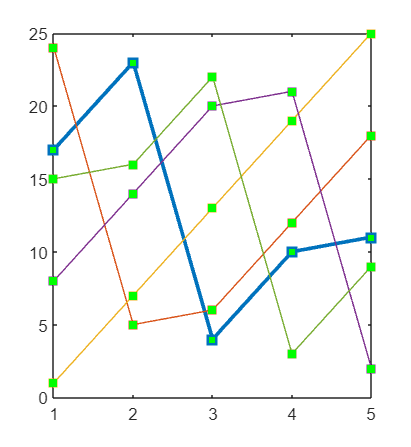

h(1).LineWidth = 2;

#### 5.2.2 Setting Multiple Property Values 

Si se desea establecer las propiedades de cada línea en un valor diferente, se pueden usar matrices de celdas para almacenar todos los datos y pasarlos al comando `set`. Por ejemplo, creamos un gráfico y guardamos los identificadores de línea.

figure
y = magic(5);
h = plot(y);

Supongamos que se desea agregar diferentes marcadores a cada línea y colorear la cara del marcador del mismo color que la línea. Debemos definir dos matrices de celdas: una que contenga los nombres de las propiedades y la otra que contenga los valores deseados de las propiedades.

La matriz de celdas `prop_name` contiene dos elementos:

prop_name(1) = {'Marker'};
prop_name(2) = {'MarkerFaceColor'};

La matriz de celdas `prop_values` contiene 10 valores: cinco valores para la propiedad `Marker `y cinco valores para la propiedad `MarkerFaceColor`. Además, se observa que `prop_values` es una matriz de celdas bidimensional. La primera dimensión indica a qué identificador en `h` se aplican los valores y la segunda dimensión indica a qué propiedad se asigna el valor:

prop_values(1,1) = {'s'};
prop_values(1,2) = {h(1).Color};
prop_values(2,1) = {'d'};
prop_values(2,2) = {h(2).Color};
prop_values(3,1) = {'o'};
prop_values(3,2) = {h(3).Color};
prop_values(4,1) = {'p'};
prop_values(4,2) = {h(4).Color};
prop_values(5,1) = {'h'};
prop_values(5,2) = {h(5).Color};

A `MarkerFaceColor` siempre se le asigna el valor del color de la línea correspondiente.

Después de definir las matrices de celdas, llamamos a `set `para especificar los nuevos valores de propiedad:

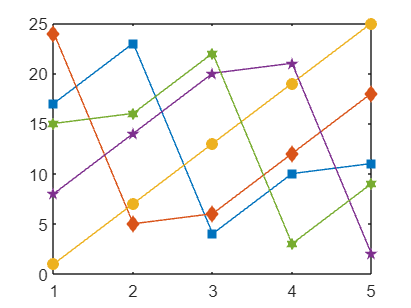

set(h,prop_name,prop_values)

### 5.3 Functions for Working with Objects

A continuación, se presentan las funciones comúnmente utilizadas cuando se trabaja con objetos:

- `allchild`**:** Encuentra todos los hijos de objetos especificados.

- `ancestor`**:** Encuentra el ancestro del objeto gráfico.

- `copyobj`**: **Copiar objeto gráfico.

- `delete`**:** Eliminar un objeto.

- `findall`**: **Encuentra todos los objetos gráficos (incluidos los identificadores ocultos).

- `findobj`**:** Encuentra los identificadores de objetos que tienen valores de propiedad específicos.

- `gca`**: **Devuelve el identificador de los ejes actuales.

- `gcf`**: **Devuelve el identificador de la figura actual.

- `gco`**:** Devuelve el identificador del objeto actual.

- `get`**:** Consulta los valores de las propiedades de un objeto.

- `ishandle`**:** Verdadero si el valor es un identificador de objeto válido.

- `set`**:** Establecer los valores de las propiedades de un objeto.

### 5.4 Passing Arguments 

Se pueden definir funciones de trazado especializadas para simplificar la creación de gráficos personalizados. Al definir una función, se pueden pasar argumentos como funciones de trazado de MATLAB.

El siguiente ejemplo muestra una función de MATLAB que evalúa una expresión matemática en el rango especificado en el argumento de entrada `x` y luego traza los resultados. Una segunda llamada a la función `plot` traza el valor medio de los resultados como una línea roja.

La función modifica los ticks del eje `y `según los valores calculados. Las etiquetas de los ejes y un título completan el gráfico personalizado.

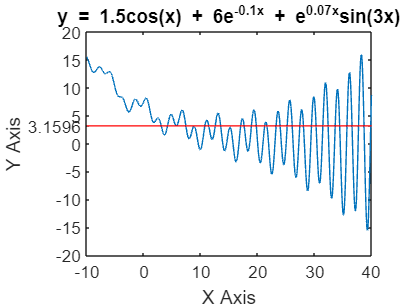

x = -10:.005:40;
plotFunc(x)

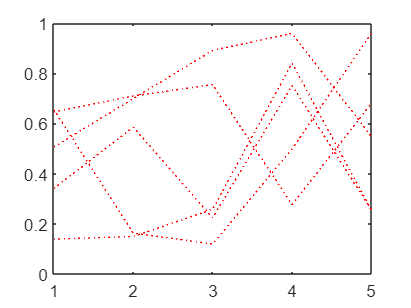

h = findobj('Type','patch');
plot(rand(5),'r:')

h = findobj('Type','line','Color','r','LineStyle',':');
h = findobj(gca,'Type','text','String','\pi/2');

function plotFunc(x)
 y = 1.5*cos(x) + 6*exp(-.1*x) + exp(.07*x).*sin(3*x);
 ym = mean(y);
 hfig = figure('Name','Function and Mean');
 hax = axes('Parent',hfig);
 plot(hax,x,y)
 hold on
 plot(hax,[min(x) max(x)],[ym ym],'Color','red')
 hold off
 ylab = hax.YTick;
 new_ylab = sort([ylab, ym]);
 hax.YTick = new_ylab;
 title ('y = 1.5cos(x) + 6e^{-0.1x} + e^{0.07x}sin(3x)')
 xlabel('X Axis')
 ylabel('Y Axis')
end

Se define un valor para el argumento de entrada y llama a la función:

% x = -10:.005:40;
% plotFunc(x)

### 5.5 Finding the Handles of Existing Objects

La función `findobj` permite obtener los identificadores de objetos gráficos buscando objetos con valores de propiedad particulares. Con `findobj se `pueden especificar los valores de cualquier combinación de propiedades, lo que facilita elegir un objeto entre muchos. `findobj `también reconoce expresiones regulares.

#### 5.5.1 Finding All Objects of a Certain Type

Debido a que todos los objetos tienen una propiedad Tipo que identifica el tipo de objeto, se pueden encontrar los identificadores de todas las apariciones de un tipo particular de objeto. Por ejemplo:

% h = findobj('Type','patch');

Encuentra los identificadores de todos los objetos de parche.

#### 5.5.2 Finding Objects with a Particular Property

Se pueden especificar varias propiedades para limitar la búsqueda. Por ejemplo:

% plot(rand(5),'r:')
% h = findobj('Type','line','Color','r','LineStyle',':');

Encuentra los identificadores de todas las líneas de puntos rojas.

#### 5.5.3 Limiting the Scope of the Search

Se puede especificar el punto de partida en la jerarquía de objetos pasando el identificador de la figura o los ejes iniciales como primer argumento. Por ejemplo:

% h = findobj(gca,'Type','text','String','\pi/2');

Encuentra `π/2 `sólo dentro de los ejes actuales.